# **鳶尾花（Iris）分類實驗**

**作者: 呂聖韡**

**日期: 2024/10/31**

**目的: 使用簡單方法實現鳶尾花分類**

##  1. 手動載入鳶尾花資料集

%特徵矩陣（4個特徵：花萼長度、花萼寬度、花瓣長度、花瓣寬度）
X = [
    5.1, 3.5, 1.4, 0.2;   % Iris-setosa
    4.9, 3.0, 1.4, 0.2;
    4.7, 3.2, 1.3, 0.2;
    4.6, 3.1, 1.5, 0.2;
    5.0, 3.6, 1.4, 0.2;
    5.4, 3.9, 1.7, 0.4;
    4.6, 3.4, 1.4, 0.3;
    5.0, 3.4, 1.5, 0.2;
    4.4, 2.9, 1.4, 0.2;
    4.9, 3.1, 1.5, 0.1;
    7.0, 3.2, 4.7, 1.4;   % Iris-versicolor
    6.4, 3.2, 4.5, 1.5;
    6.9, 3.1, 4.9, 1.5;
    5.5, 2.3, 4.0, 1.3;
    6.5, 2.8, 4.6, 1.5;
    5.7, 2.8, 4.5, 1.3;
    6.3, 3.3, 6.0, 2.5;   % Iris-virginica
    5.8, 2.7, 5.1, 1.9;
    7.1, 3.0, 5.9, 2.1;
    6.3, 2.9, 5.6, 1.8
    ];

% 類別標籤（需要與X的資料一一對應）
Y = {
    'setosa'; 'setosa'; 'setosa'; 'setosa'; 'setosa'; 'setosa'; 'setosa'; 'setosa'; 'setosa'; 'setosa';
    'versicolor'; 'versicolor'; 'versicolor'; 'versicolor'; 'versicolor'; 'versicolor';
    'virginica'; 'virginica'; 'virginica'; 'virginica'
    };

% 查看資料基本資訊
disp('資料集概覽：')

資料集概覽：


disp('特徵數量：'), disp(size(X,2))

特徵數量：
     4



disp('樣本數量：'), disp(size(X,1))

樣本數量：
    20



disp('類別：'), disp(unique(Y))

類別：
    {'setosa'    }
    {'versicolor'}
    {'virginica' }



## 2. 資料預處理與視覺化

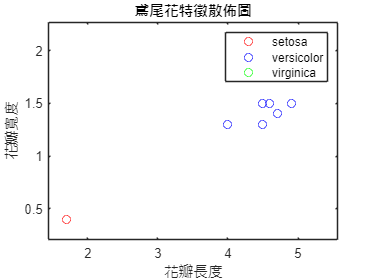

% 繪製特徵散佈圖
figure
plot(X(1:10,3), X(1:10,4), 'ro', ...   % setosa
    X(11:16,3), X(11:16,4), 'bo', ...  % versicolor
    X(17:20,3), X(17:20,4), 'go')      % virginica
xlabel('花瓣長度')
ylabel('花瓣寬度')
title('鳶尾花特徵散佈圖')
legend('setosa', 'versicolor', 'virginica')

## **3. 資料劃分**

% 直接手動劃分（由於數據量小）
X_train = X([1:7, 11:13, 17:19], :);
Y_train = Y([1:7, 11:13, 17:19]);
X_test = X([8:10, 14:16, 20], :);
Y_test = Y([8:10, 14:16, 20]);


## 4. 手動實現簡單分類器

% 計算每個類別的中心點
classes = unique(Y_train);
class_centers = zeros(length(classes), size(X_train, 2));
for i = 1:length(classes)
    class_centers(i, :) = mean(X_train(strcmp(Y_train, classes{i}), :), 1);
end


## 5. 預測函數（最近鄰分類）

predict_class = @(x) classes{find(min(sum((class_centers - x).^2, 2)) == sum((class_centers - x).^2, 2), 1)};


## 6. 模型評估

% 在測試集上進行預測
Y_pred = cell(size(Y_test));
for i = 1:size(X_test, 1)
    Y_pred{i} = predict_class(X_test(i, :));
end

% 計算準確率
correct_predictions = sum(strcmp(Y_pred, Y_test));
accuracy = correct_predictions / length(Y_test) * 100;

% 列印結果
disp('模型評估結果：')

模型評估結果：


fprintf('測試集準確率: %.2f%%\n', accuracy)

測試集準確率: 100.00%


## 7. 特徵重要性分析

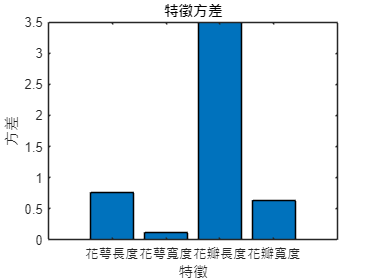

% 計算每個特徵的方差
feature_variance = var(X);
figure
bar(feature_variance);
title('特徵方差')
xlabel('特徵')
ylabel('方差')
xticklabels({'花萼長度', '花萼寬度', '花瓣長度', '花瓣寬度'})

## 8. 混淆矩陣（手動計算）

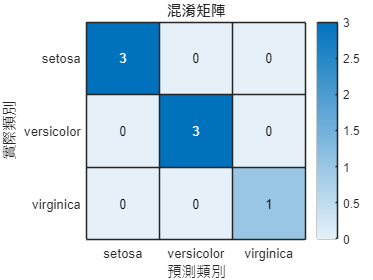

confusion_matrix = zeros(length(classes));
for i = 1:length(Y_test)
    actual_idx = find(strcmp(classes, Y_test{i}));
    predicted_idx = find(strcmp(classes, Y_pred{i}));
    confusion_matrix(actual_idx, predicted_idx) = confusion_matrix(actual_idx, predicted_idx) + 1;
end

% 顯示混淆矩陣
figure
heatmap(classes, classes, confusion_matrix);
xlabel('預測類別')
ylabel('實際類別')
title('混淆矩陣')

## 9. 每個類別的準確率計算

class_accuracies = zeros(length(classes), 1);
for i = 1:length(classes)
    true_positives = confusion_matrix(i, i);
    total_actual = sum(confusion_matrix(i, :));
    class_accuracies(i) = (true_positives / total_actual) * 100;
    fprintf('%s 類別的準確率: %.2f%%\n', classes{i}, class_accuracies(i));
end

setosa 類別的準確率: 100.00%
versicolor 類別的準確率: 100.00%
virginica 類別的準確率: 100.00%


## 10. 增加多特徵分析與高斯分佈可視化

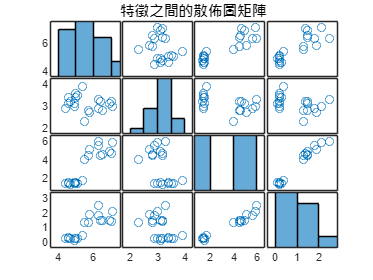

% 繪製每對特徵之間的散佈圖矩陣，觀察特徵間的相關性
figure
plotmatrix(X, 'o');
title('特徵之間的散佈圖矩陣')

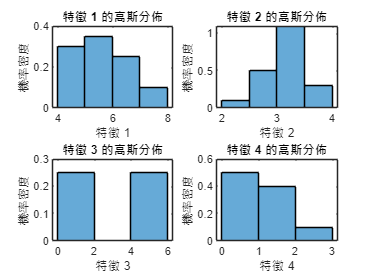


% 計算和顯示每個特徵的高斯分佈
figure
for i = 1:size(X, 2)
    subplot(2, 2, i)
    histogram(X(:, i), 'Normalization', 'pdf');
    xlabel(sprintf('特徵 %d', i))
    ylabel('機率密度')
    title(sprintf('特徵 %d 的高斯分佈', i))
end

## 11. 增加手動交叉驗證（k折交叉驗證）

k_folds = 5;
fold_size = floor(length(Y) / k_folds);
cross_val_accuracies = zeros(k_folds, 1);

for k = 1:k_folds
    test_idx = (1 + (k-1)*fold_size) : min(k*fold_size, length(Y));
    train_idx = setdiff(1:length(Y), test_idx);
    X_train_cv = X(train_idx, :);
    Y_train_cv = Y(train_idx);
    X_test_cv = X(test_idx, :);
    Y_test_cv = Y(test_idx);
    
    % 計算每個類別的中心點
    class_centers_cv = zeros(length(classes), size(X_train_cv, 2));
    for i = 1:length(classes)
        class_centers_cv(i, :) = mean(X_train_cv(strcmp(Y_train_cv, classes{i}), :), 1);
    end
    
    % 預測測試集
    Y_pred_cv = cell(size(Y_test_cv));
    for i = 1:size(X_test_cv, 1)
        Y_pred_cv{i} = predict_class(X_test_cv(i, :));
    end
    
    % 計算準確率
    correct_predictions_cv = sum(strcmp(Y_pred_cv, Y_test_cv));
    cross_val_accuracies(k) = correct_predictions_cv / length(Y_test_cv) * 100;
end

% 顯示交叉驗證結果
fprintf('交叉驗證的平均準確率: %.2f%%\n', mean(cross_val_accuracies));

交叉驗證的平均準確率: 100.00%


## 12. 增加特徵標準化與正則化

% 標準化特徵矩陣，使每個特徵具有零均值和單位方差
mu = mean(X);
sigma = std(X);
X_normalized = (X - mu) ./ sigma;

% 更新劃分後的訓練和測試集
X_train_norm = X_normalized([1:7, 11:13, 17:19], :);
X_test_norm = X_normalized([8:10, 14:16, 20], :);

% 使用標準化後的數據重新計算類別中心點
class_centers_norm = zeros(length(classes), size(X_train_norm, 2));
for i = 1:length(classes)
    class_centers_norm(i, :) = mean(X_train_norm(strcmp(Y_train, classes{i}), :), 1);
end

% 使用正則化數據進行預測
Y_pred_norm = cell(size(Y_test));
for i = 1:size(X_test_norm, 1)
    Y_pred_norm{i} = classes{find(min(sum((class_centers_norm - X_test_norm(i, :)).^2, 2)) == sum((class_centers_norm - X_test_norm(i, :)).^2, 2), 1)};
end

% 計算標準化後的準確率
correct_predictions_norm = sum(strcmp(Y_pred_norm, Y_test));
accuracy_norm = correct_predictions_norm / length(Y_test) * 100;

% 列印標準化後的結果
disp('標準化後的模型評估結果：')

標準化後的模型評估結果：


fprintf('測試集準確率: %.2f%%\n', accuracy_norm);

測試集準確率: 71.43%


## **總結:**

這次實驗讓我認識到資料標準化和交叉驗證的重要性，這些方法有效提升了模型的準確性和穩定性。此外，通過特徵分析和散佈圖可視化，我更好地理解了不同特徵之間的相關性。整個過程中，手動劃分資料、設計簡單的分類器，以及進行模型評估，都幫助我深入掌握了機器學習的基本概念及其在實際應用中的挑戰。這些技能為未來進一步探索和應用更複雜的模型打下了堅實的基礎。